clear
clc

% NEEDS TO BE IN ./SRC/ FOLDER
system("make clean -f .\Makefile");

rm -f *.exe
rm -f libs\*.exe
rm -f A_sparse.txt b.txt x.txt


system("make main -f .\Makefile");

g++ -Wall -Wpedantic FiniteDifferences.cpp -O2 -o FiniteDifferences.exe



fp = fopen("input.dat","r+");
for i = 1:5
    fgetl(fp);
end
fprintf(fp,"is_cracked 0");
fclose(fp);

N = 750;
M = system(".\FiniteDifferences.exe " + string(N));
x = load(".\x.txt");

v1.x = round((131.25)/400 * N);
v1.y = round((125)/250 * M);
v2.x = round((400-131.25)/400 * N);
v2.y = round((125)/250 * M);

v3.x = round((151.39)/400 * N);
v3.y = round((250 - 76.39)/250 * M);
v4.x = round((400 - 151.39)/400 * N);
v4.y = round((76.39)/250 * M);
DV1_ = abs(x(v1.x + N * (v1.y - 1)) - x(v2.x + N * (v2.y - 1))) * 1e6;
DV2_ = abs(x(v3.x + N * (v3.y - 1)) - x(v4.x + N * (v4.y - 1))) * 1e6;

fp = fopen("input.dat","r+");
for i = 1:5
    fgetl(fp);
end
fprintf(fp,"is_cracked 1");
fclose(fp);

crack_angle_range = 5:5:90;
k = 1;
for crack_angle = crack_angle_range
    fp = fopen("input.dat","r+");
    for i = 1:9
        fgetl(fp);
    end
    fprintf(fp,"crack_angle " + sprintf("%.2f",crack_angle));
    fclose(fp);

    system(".\FiniteDifferences.exe " + string(N));
    x = load(".\x.txt");

    DV1(k) = abs(x(v1.x + N * (v1.y - 1)) - x(v2.x + N * (v2.y - 1))) * 1e6; %#ok
    DV2(k) = abs(x(v3.x + N * (v3.y - 1)) - x(v4.x + N * (v4.y - 1))) * 1e6; %#ok
    k = k + 1;
end

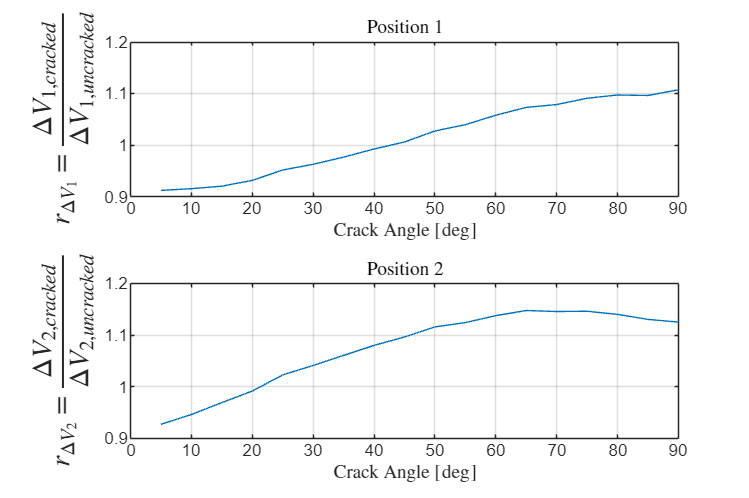

r1 = DV1/DV1_;
r2 = DV2/DV2_;
max_r1 = max(r1);
max_r2 = max(r2);
min_r1 = min(r1);
min_r2 = min(r2);

fg = figure("Position",[0,0,1200,800]);
t = tiledlayout(2,1);
nexttile();
plot(crack_angle_range, DV1/DV1_)
title("Position 1","Interpreter","latex")
grid on
xlabel("Crack Angle $[\deg]$","Interpreter","latex")
ylabel("$r_{\Delta V_1} = \frac{\Delta V_{1,cracked}}{\Delta V_{1,uncracked}}$", ...
    "Interpreter","latex","FontSize",14)
xlim([0,90])
ylim([round(0.95*min_r1,1),round(1.05*max_r1,1)])

nexttile();
plot(crack_angle_range, DV2/DV2_)
title("Position 2","Interpreter","latex")
grid on
xlabel("Crack Angle $[\deg]$","Interpreter","latex")
ylabel("$r_{\Delta V_2} = \frac{\Delta V_{2,cracked}}{\Delta V_{2,uncracked}}$", ...
    "Interpreter","latex","FontSize",14)
xlim([0,90])
ylim([round(0.95*min_r2,1),round(1.05*max_r2,1)])

saveas(fg,"CrackAnglePlots","svg");